# MODEL A SUNFLOWER WITH THE GOLDEN RATIO

It is well-documented that the Golden Ratio is observed in the angular geometry of seeds in sunflowers, coneflowers and pinecones, as well as other plants and natural phenomena. ([http://www.mcs.surrey.ac.uk/Personal/R.Knott/Fibonacci/fibnat.html](http://www.mcs.surrey.ac.uk/Personal/R.Knott/Fibonacci/fibnat.html))

However, little regard has been paid, it seems, to the distance of each seed from the center. When I looked at sunflowers and coneflowers, I noticed that the density of seeds is not uniform throughout. Seeds toward the center are smaller than the seeds near the edges, and thus, their density is greater.

This file makes a connection between the Golden Ratio and the seed distance from the center of the sunflower. This accounts for the growth of each seed over time, and provides a better model for seed location than linear distance from center.

AUTHOR: Joseph Kirk (c) 5/2006 EMAIL: jdkirk630 at gmail dot com

## THE GOLDEN RATIO (PHI)


$$\phi = \frac{\sqrt{5}-1}{2}$$


phi = (sqrt(5)-1)/2

phi = 0.6180

## NUMBER OF SEEDS

n = 2618;

## SEED DISTANCE FROM CENTER

The seed distances are raised to the Golden Ratio power


$$\rho_k = (k-1)^\phi$$


rho = (0:n-1).^phi

rho =          0    1.0000    1.5348    1.9719    2.3556    2.7039    3.0264    3.3289    3.6153    3.8883    4.1499    4.4017    4.6448    4.8804    5.1091    5.3317    5.5486    5.7605    5.9676    6.1704    6.3691    6.5641    6.7556    6.9438    7.1288    7.3110    7.4903    7.6671    7.8414    8.0133    8.1830    8.3505    8.5160    8.6795    8.8411    9.0009    9.1590    9.3154    9.4702    9.6235    9.7752    9.9256   10.0745   10.2221   10.3683   10.5134   10.6571   10.7997   10.9412   11.0815


## SEED ANGLE

A cirlce contains `2*pi` radians, so `2*pi*phi` cuts the circle by the Golden Ratio


$$\theta_k = (k-1)*2\pi\phi$$


theta = (0:n-1)*2*pi*phi

theta =          0    3.8832    7.7664   11.6497   15.5329   19.4161   23.2993   27.1826   31.0658   34.9490   38.8322   42.7154   46.5987   50.4819   54.3651   58.2483   62.1316   66.0148   69.8980   73.7812   77.6644   81.5477   85.4309   89.3141   93.1973   97.0806  100.9638  104.8470  108.7302  112.6134  116.4967  120.3799  124.2631  128.1463  132.0296  135.9128  139.7960  143.6792  147.5624  151.4457  155.3289  159.2121  163.0953  166.9785  170.8618  174.7450  178.6282  182.5114  186.3947  190.2779


## PLOT

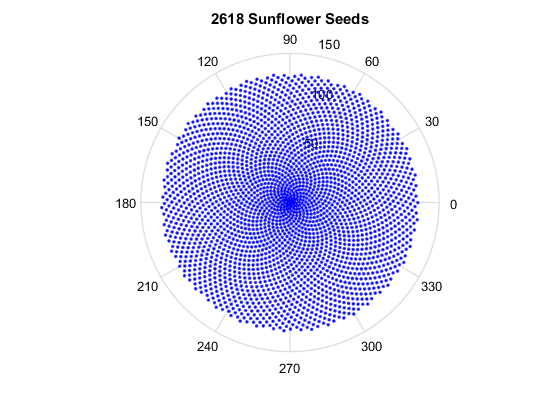

polar(theta, rho, 'b.');
title([num2str(n) ' Sunflower Seeds']);
set(gcf, 'color', 'w');